% reading data
A = readmatrix('MovieRankings36.csv');
[n,m] = size(A);
k = 5;
% initialize X and Y
rng('default');
X = rand(n,k);
Y = rand(k,m);

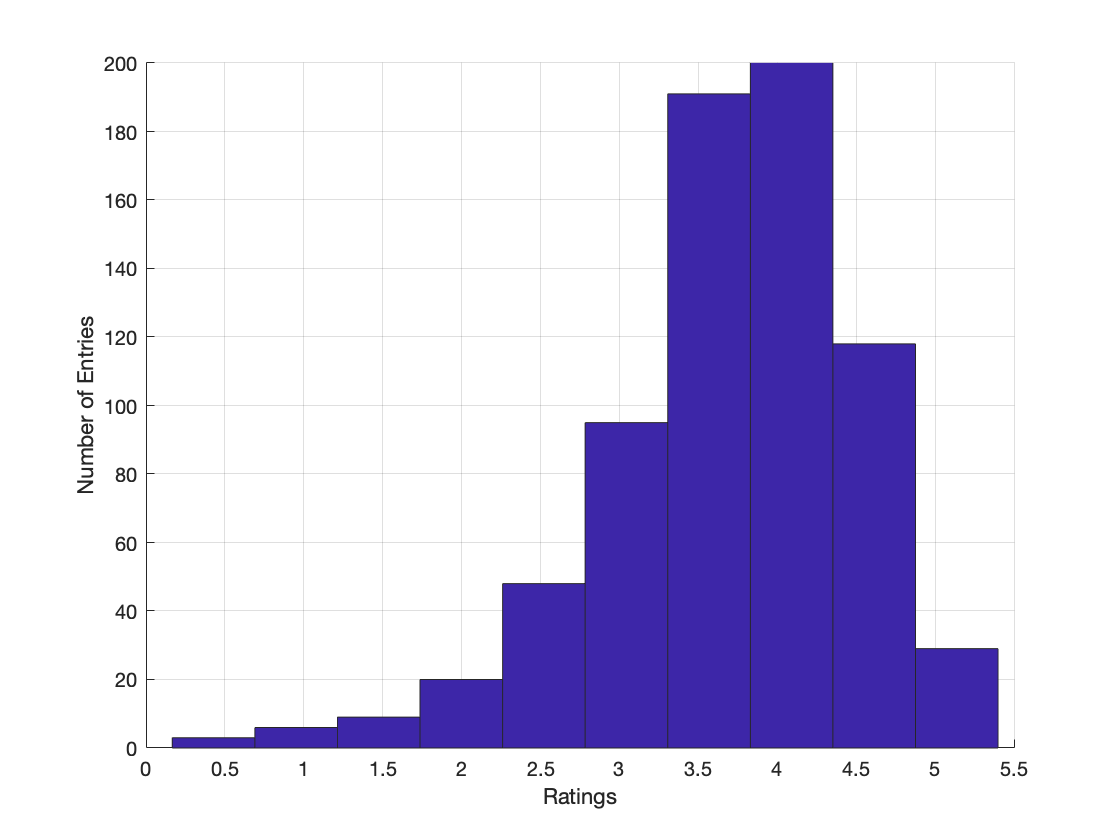

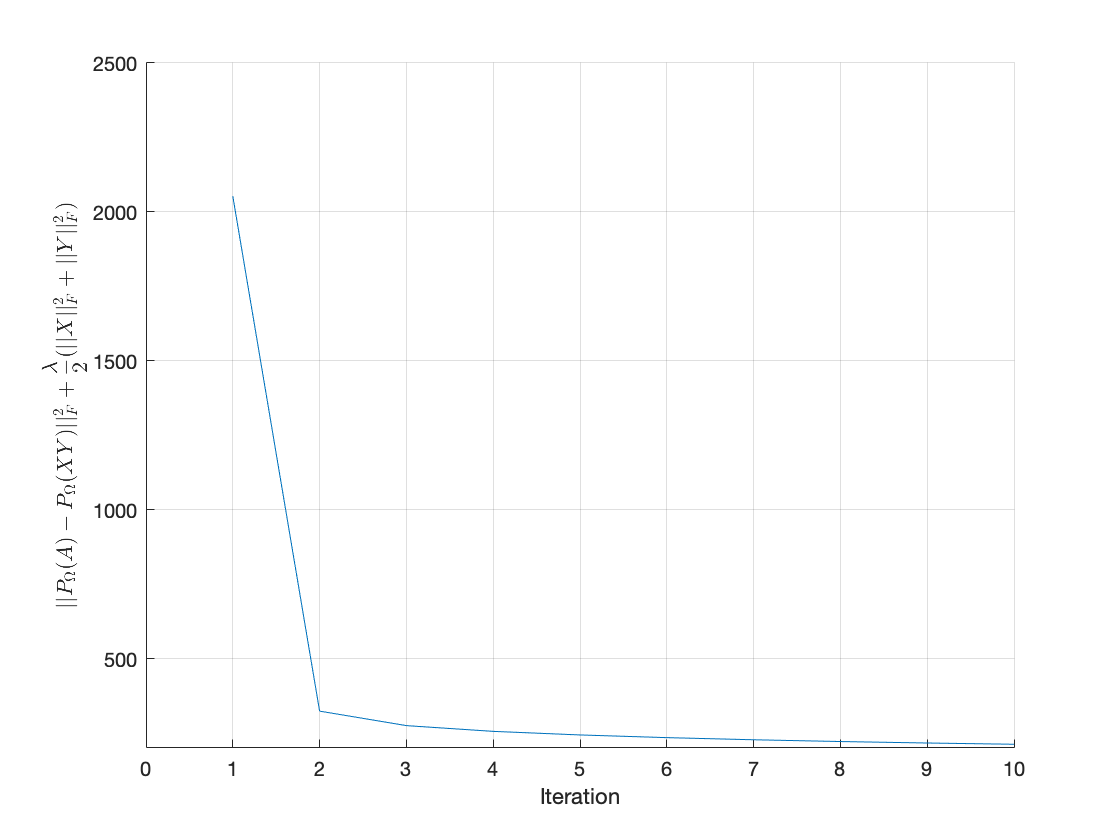

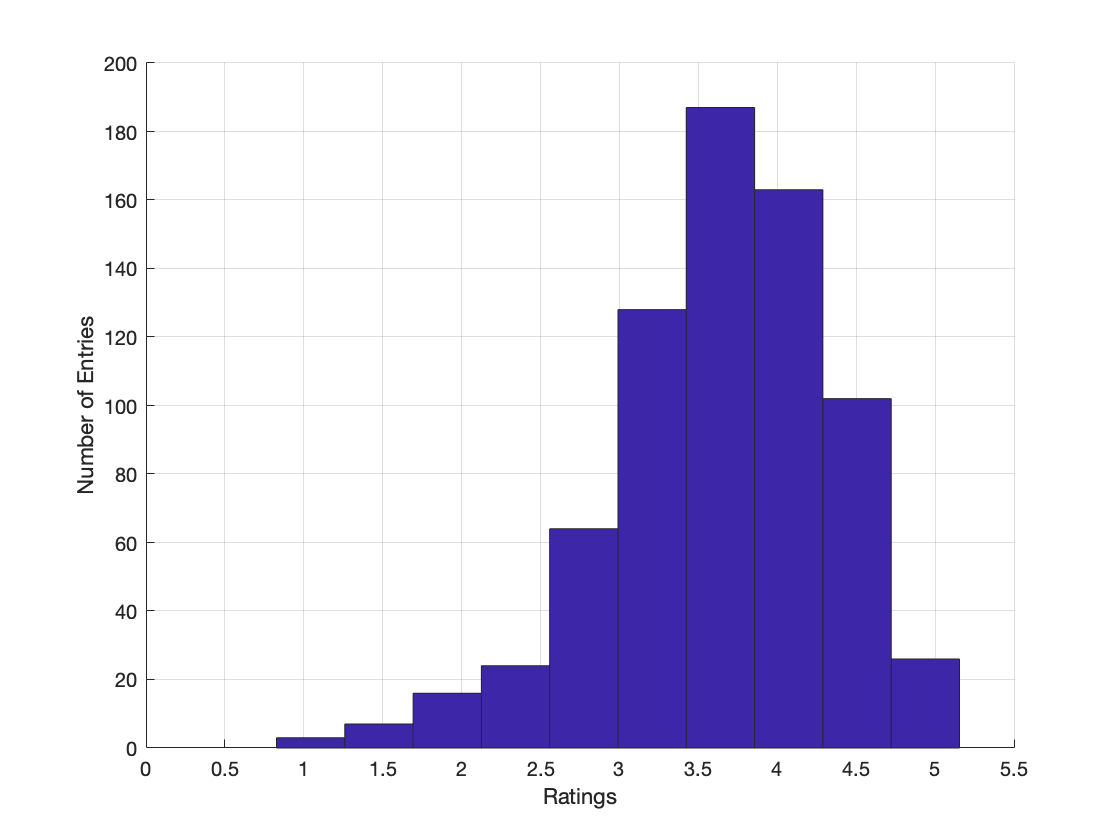

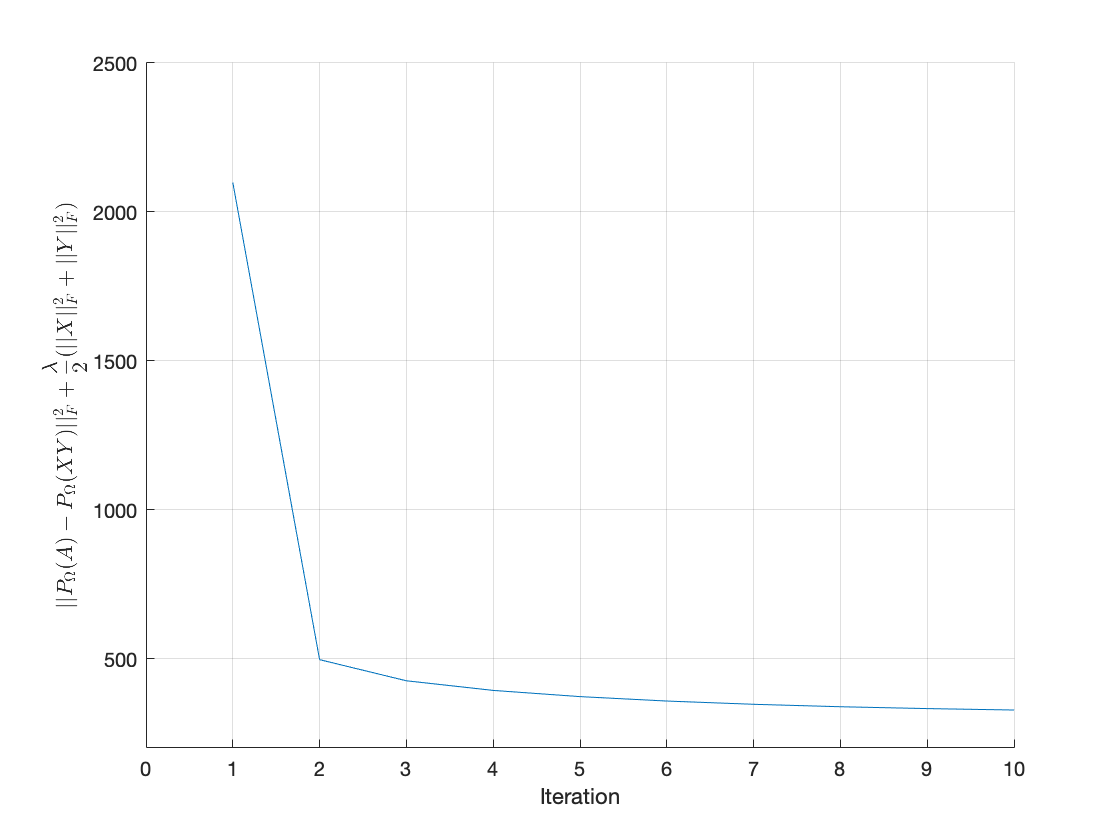

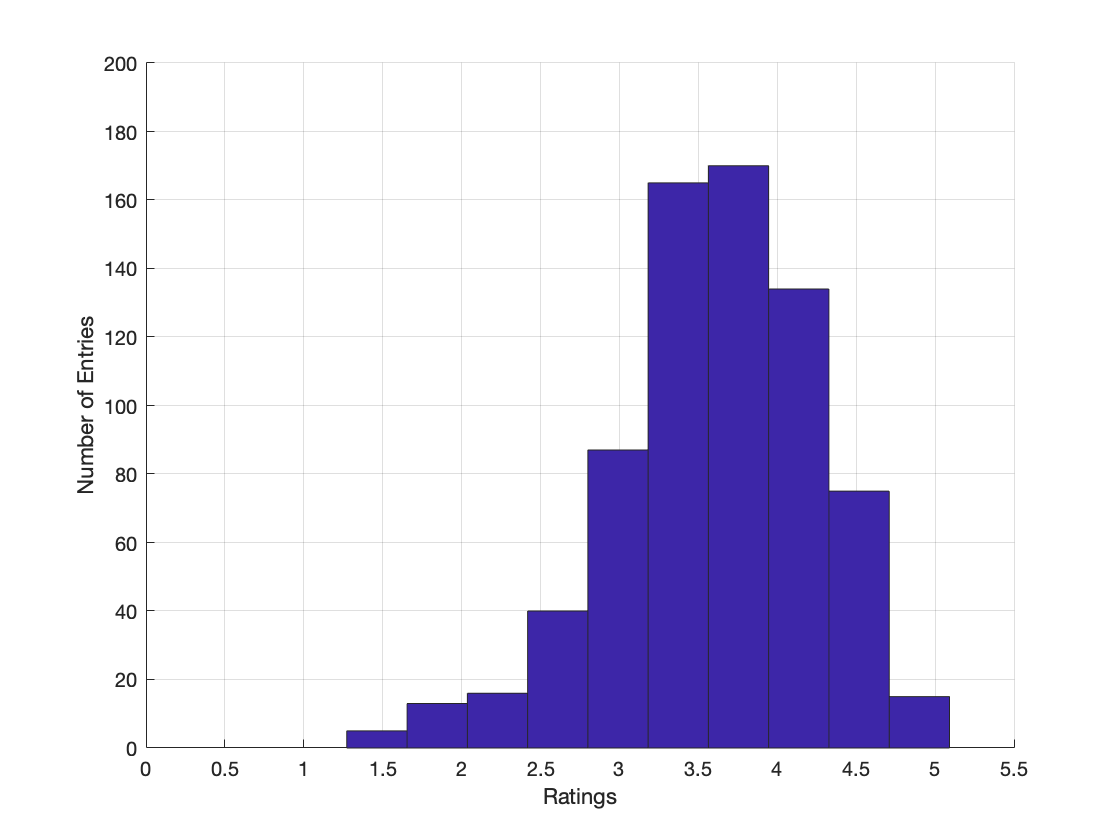

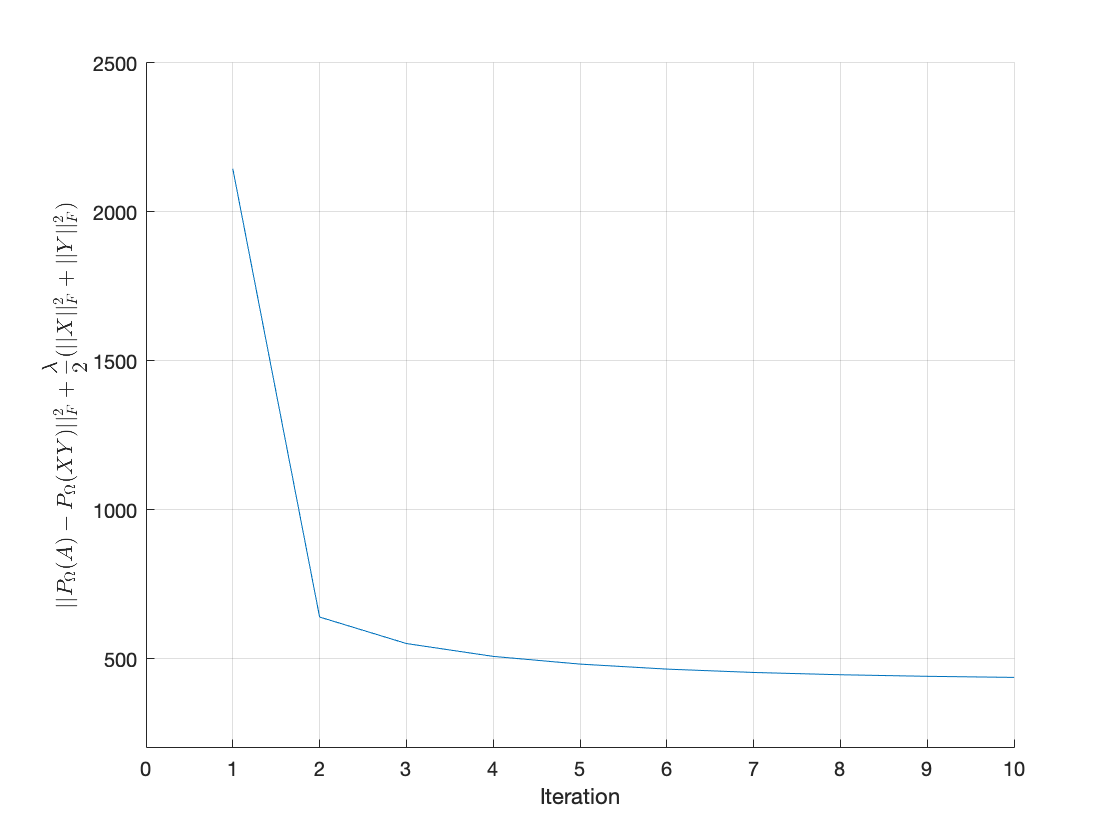

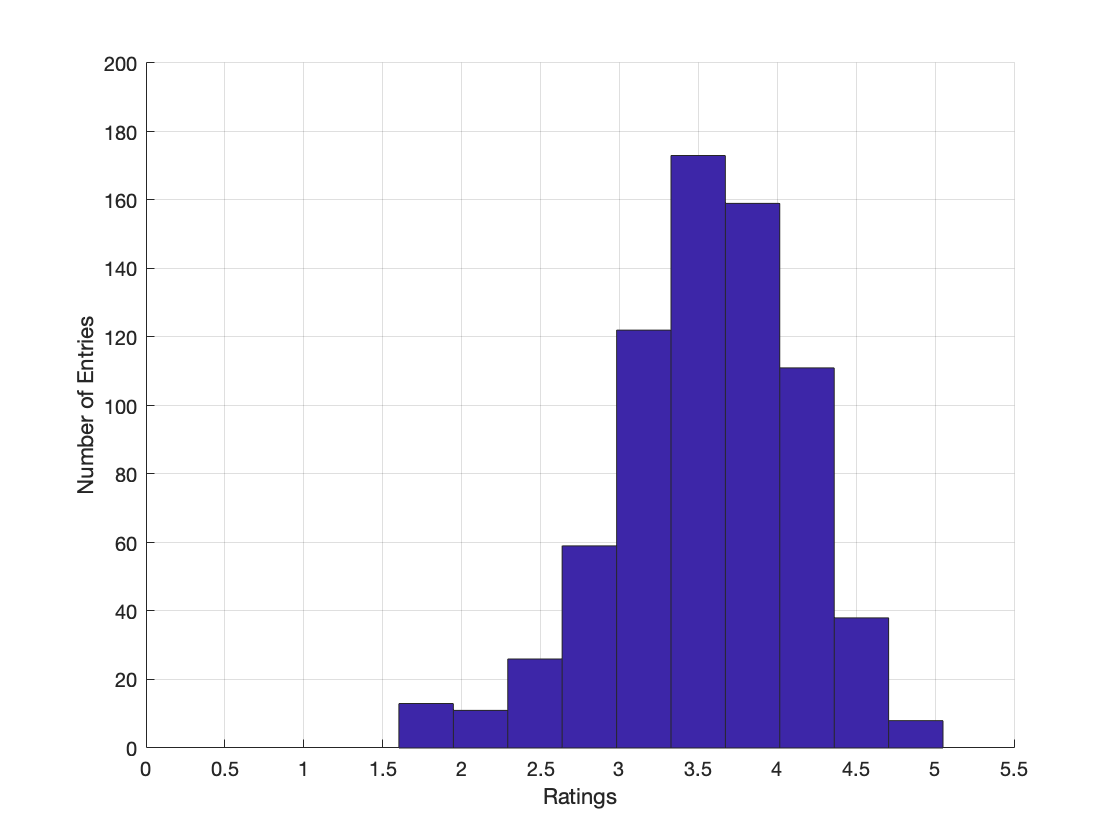

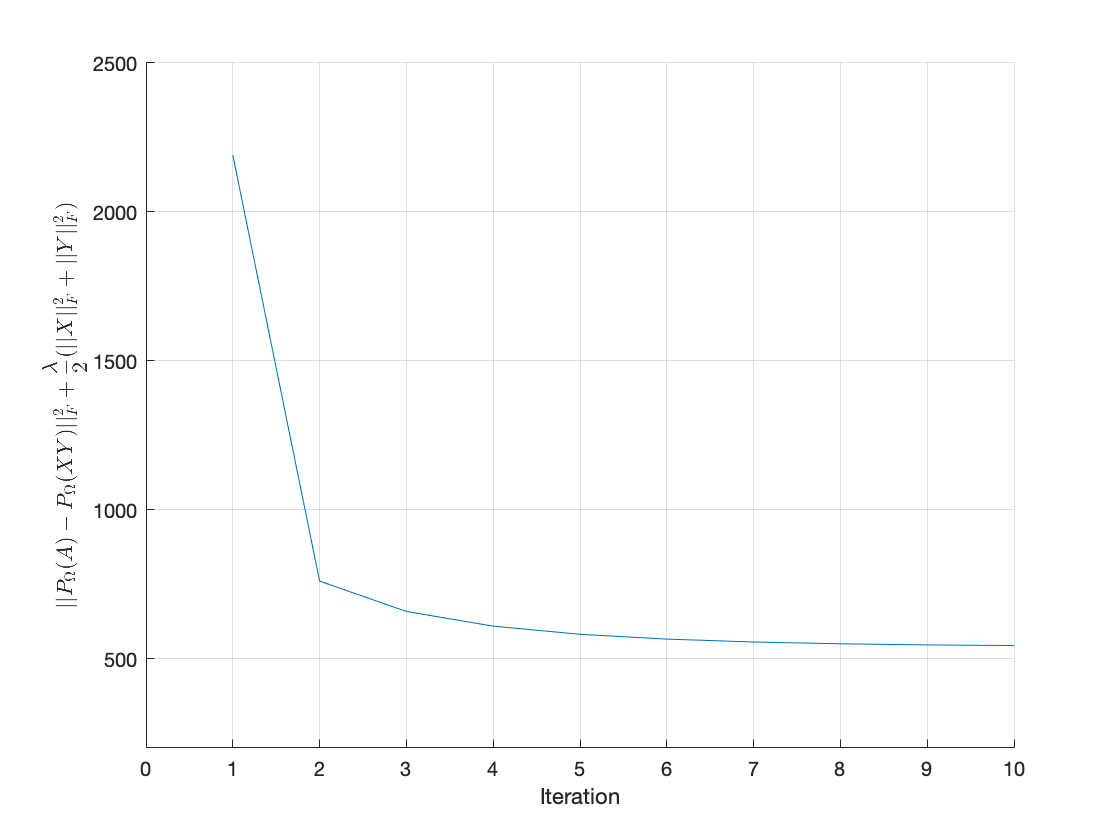

% testing lambda = 1 : 10
maxiter = 10;
Xs = zeros(10,n,k);
Ys = zeros(10,k,m);
for lambda = 1:9
    [fro,X_out,Y_out] = AD(A,k,lambda,maxiter,X,Y);
    M = X_out * Y_out;
    close all;
    figure;
    hold on; grid;
    hist(reshape(M,[n*m 1]));
    xlim([0,5.5]);
    ylim([0,200]);
    xlabel('Ratings');
    ylabel('Number of Entries');
    saveas(gcf,['figures/ad_m_' num2str(lambda) '.png']);
    close all;
    figure;
    hold on; grid;
    plot(1:maxiter+1, fro);
    ylim([200 2500]);
    xlim([0 maxiter]);
    xlabel('Iteration');
    ylabel('$$\frac{1}{2}||P_{\Omega}(A)-P_{\Omega}(XY)||_F^2+\frac{\lambda}{2}(||X||_F^2+||Y||_F^2)$$','interpreter','latex');   
    saveas(gcf,['figures/ad_' num2str(lambda) '.png']);
end

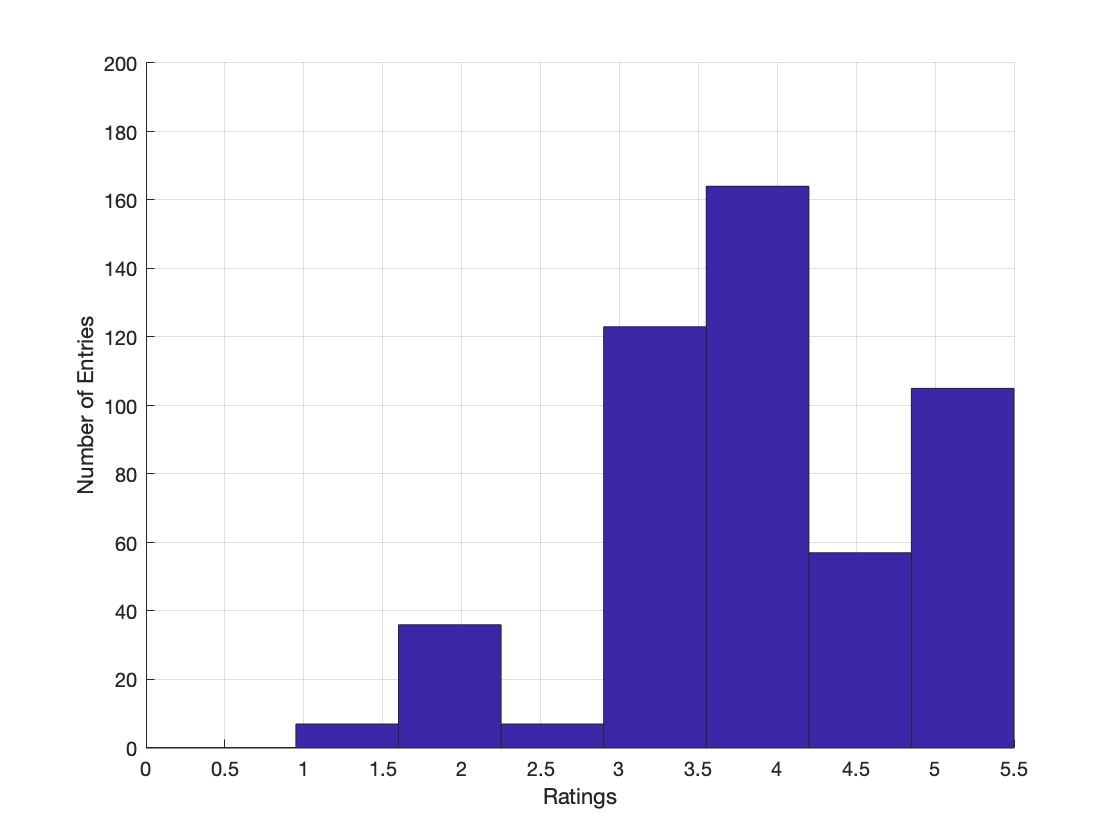

% distribution of ratings in the
% original dataset
B = A;
B(isnan(B)) = -1;
close all;
figure;
hold on; grid;
hist(reshape(B,[n*m 1]));
xlim([0,5.5]);
ylim([0,200]);
xlabel('Ratings');
ylabel('Number of Entries');
saveas(gcf,['figures/ad_a.png']);

% initialize M for nuclear norm trick
M0 = rand(n,m);

% nuclear norm trick
maxiter = 10

maxiter = 10

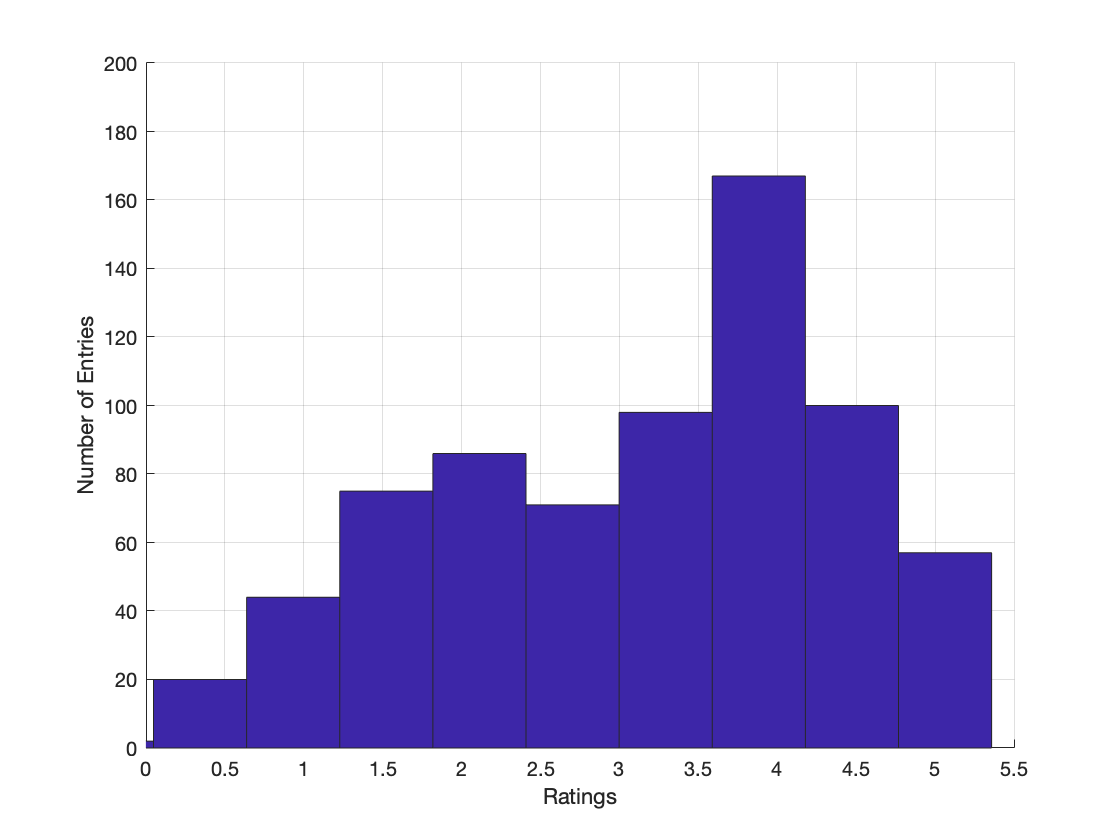

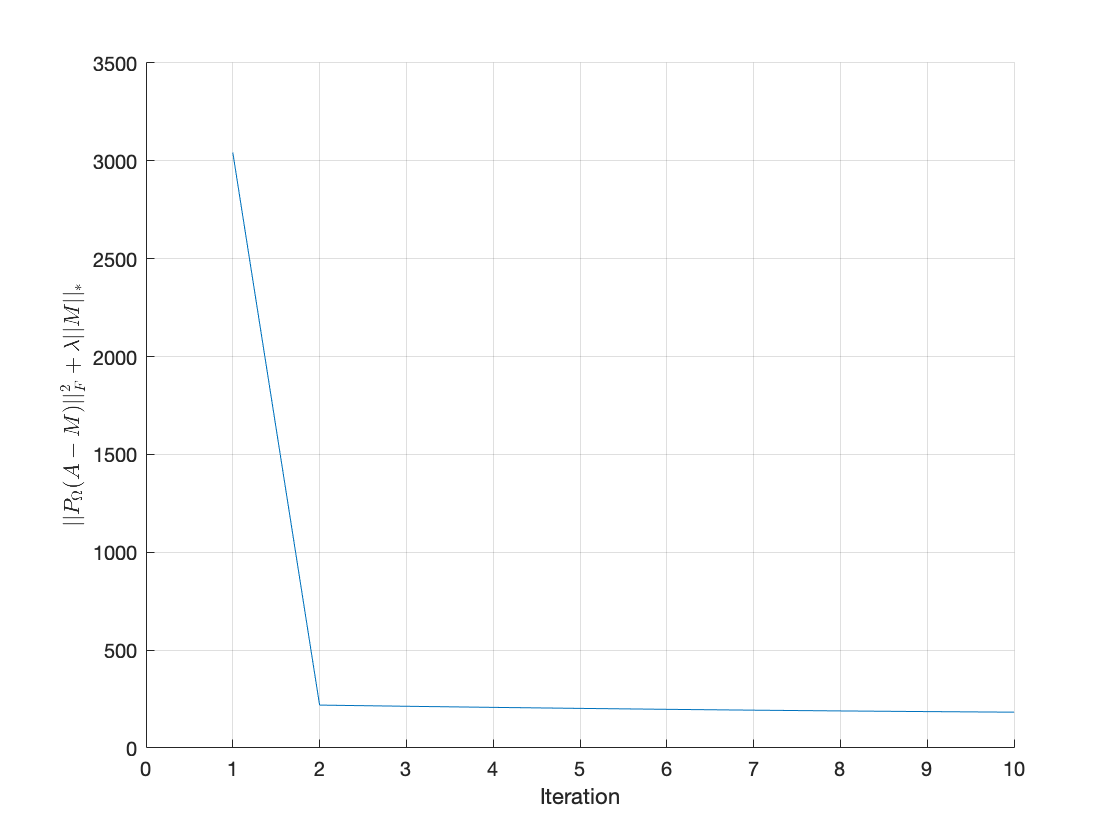

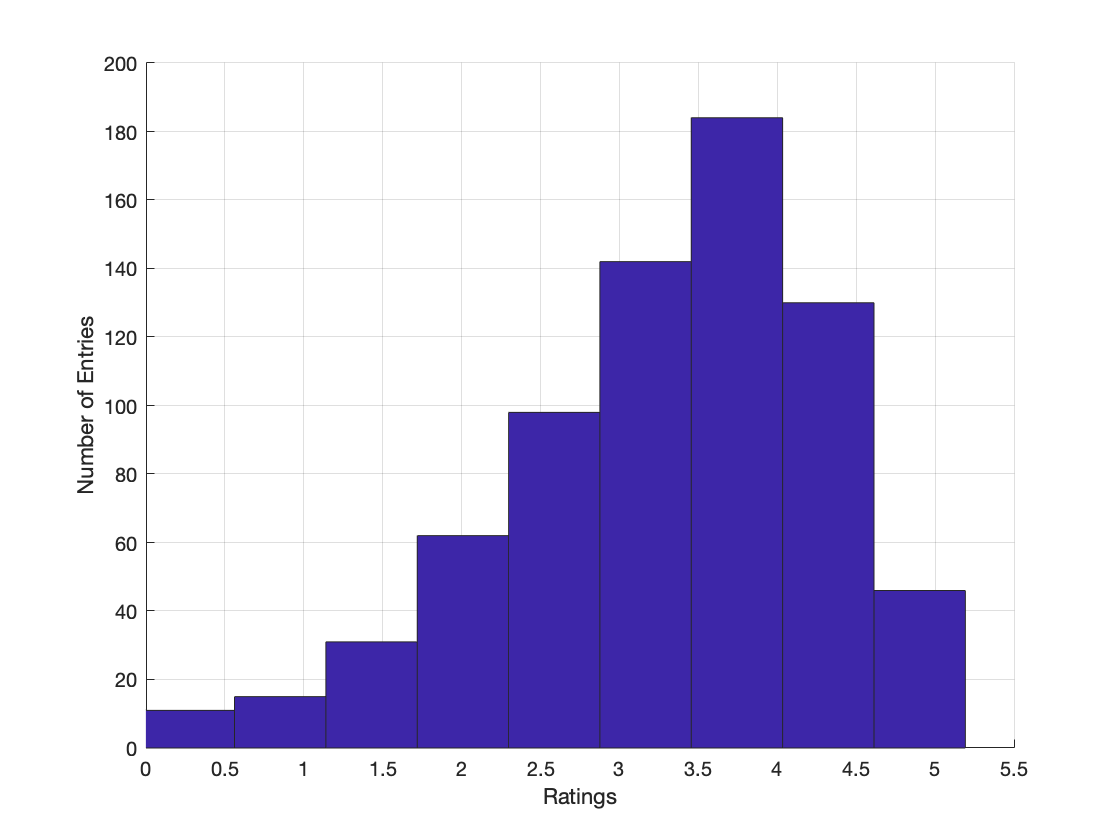

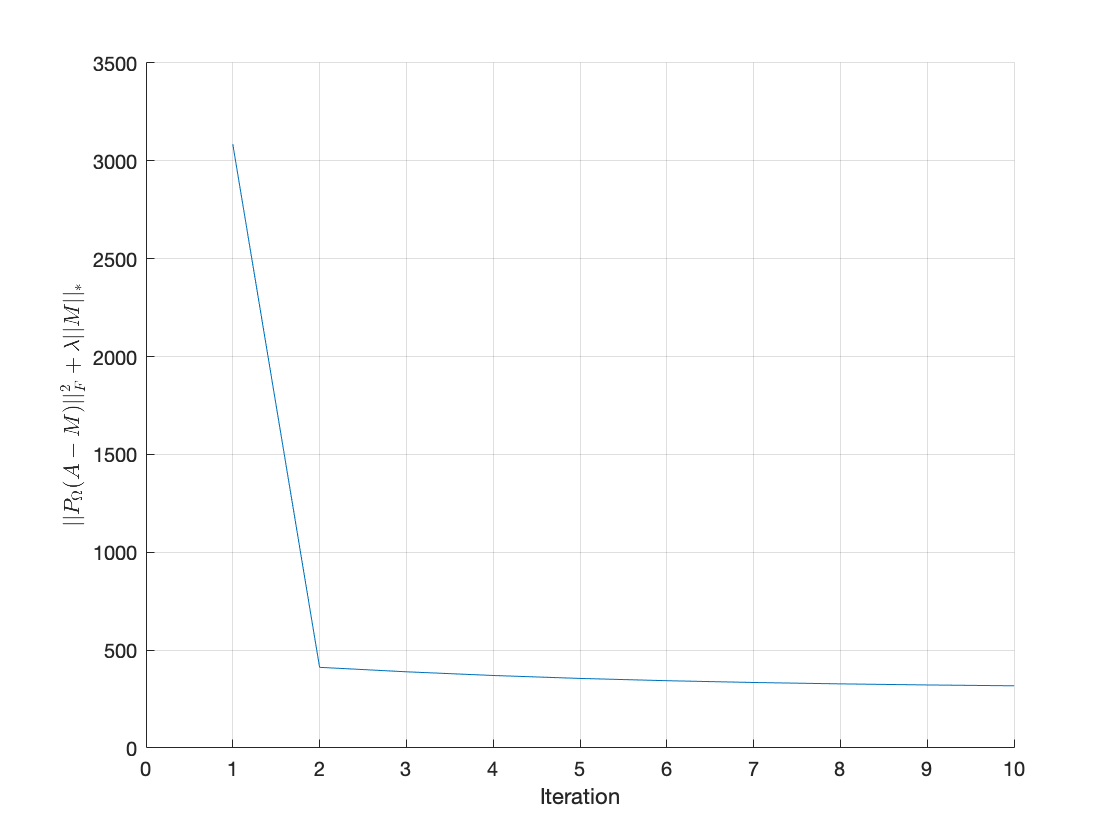

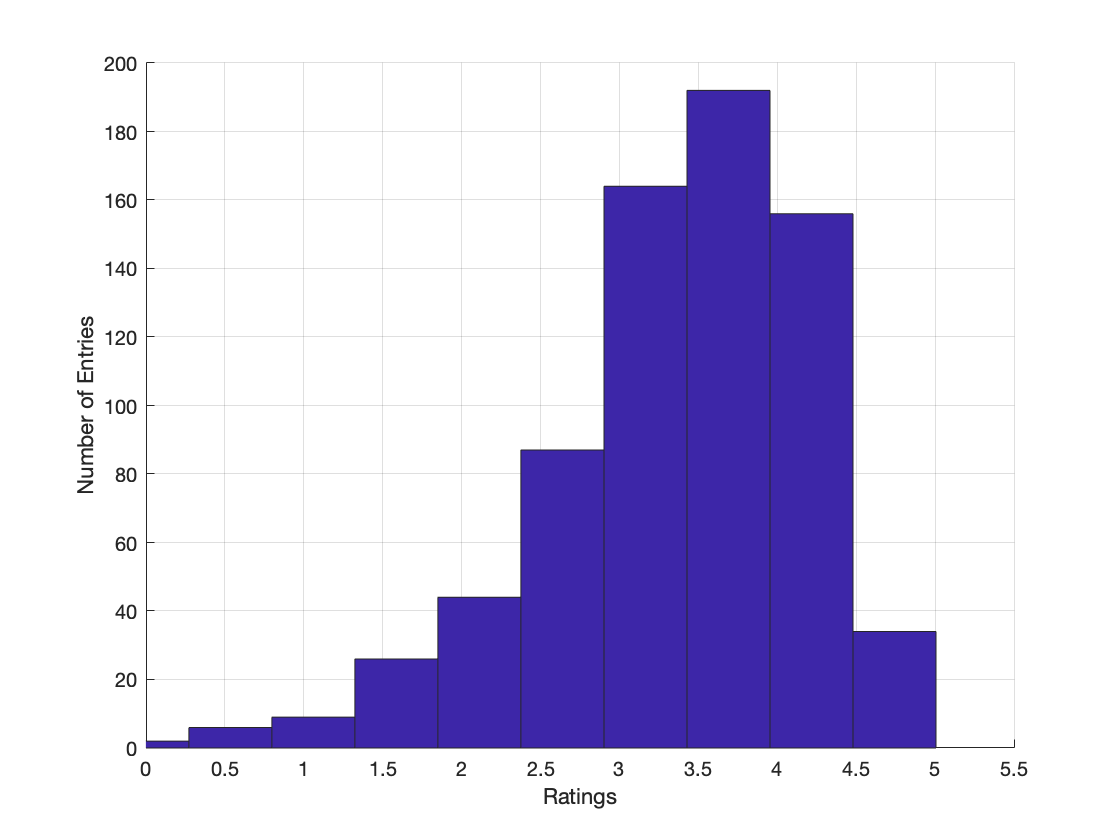

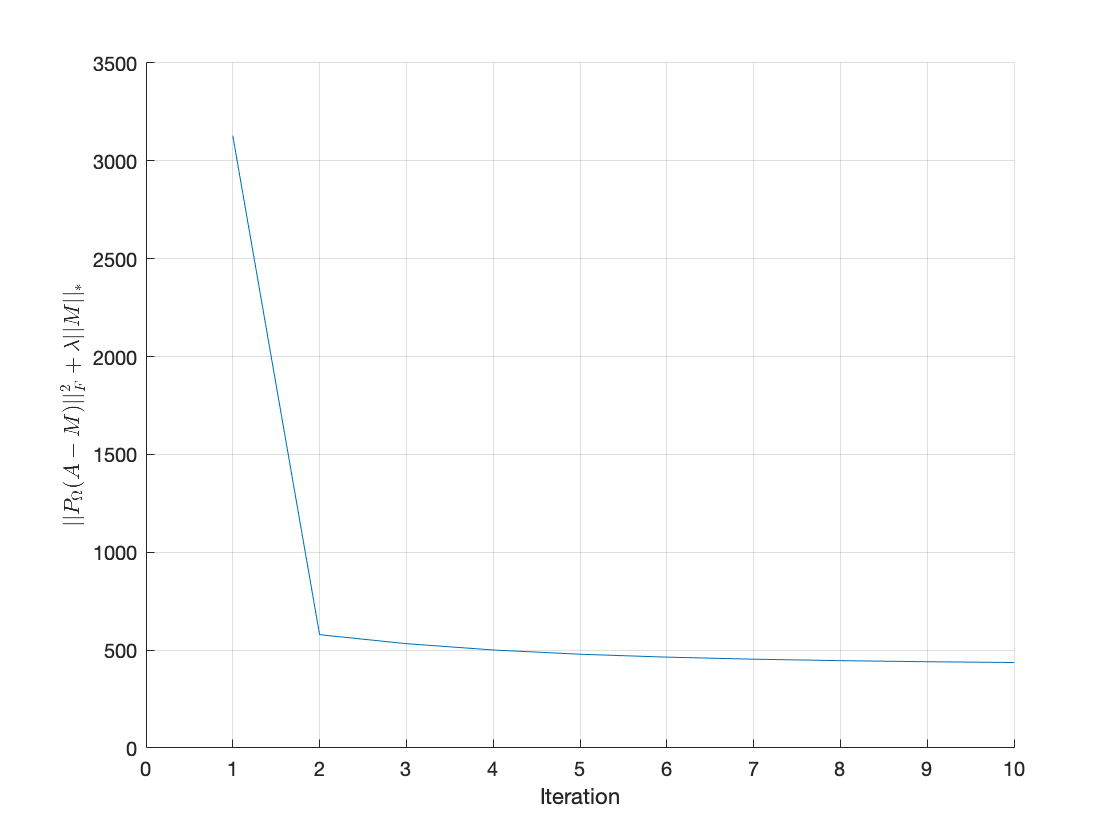

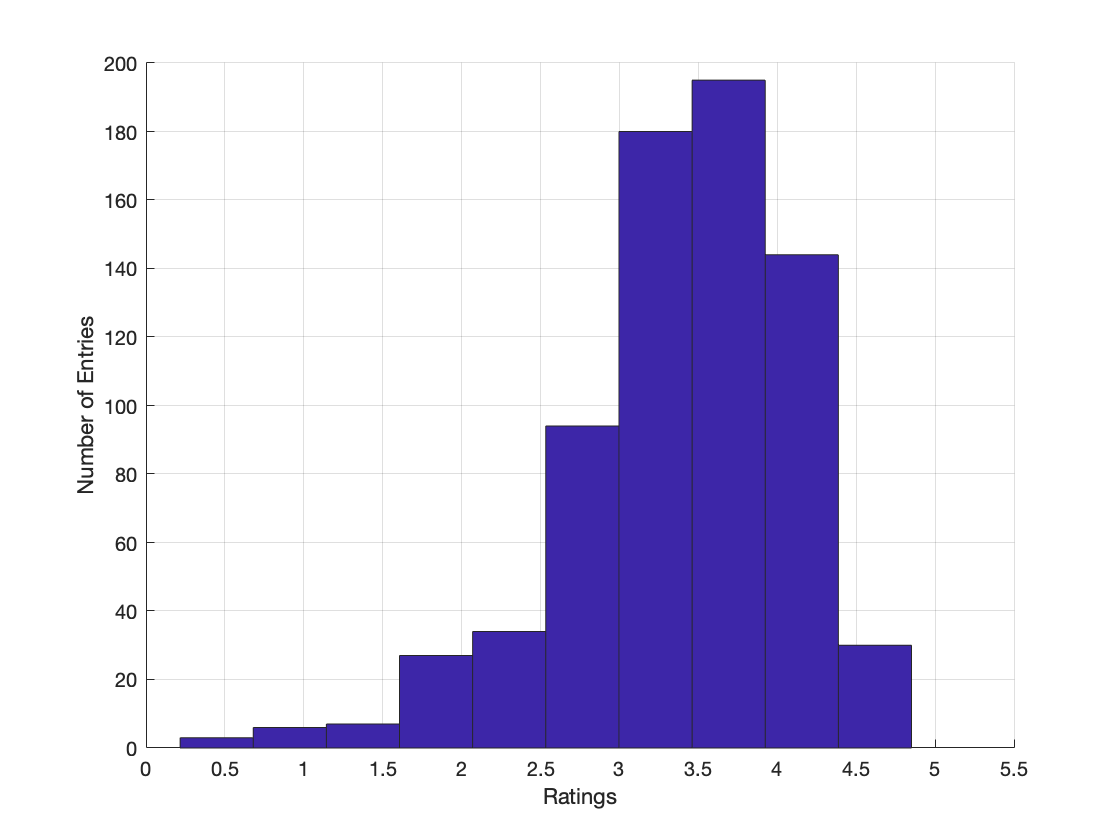

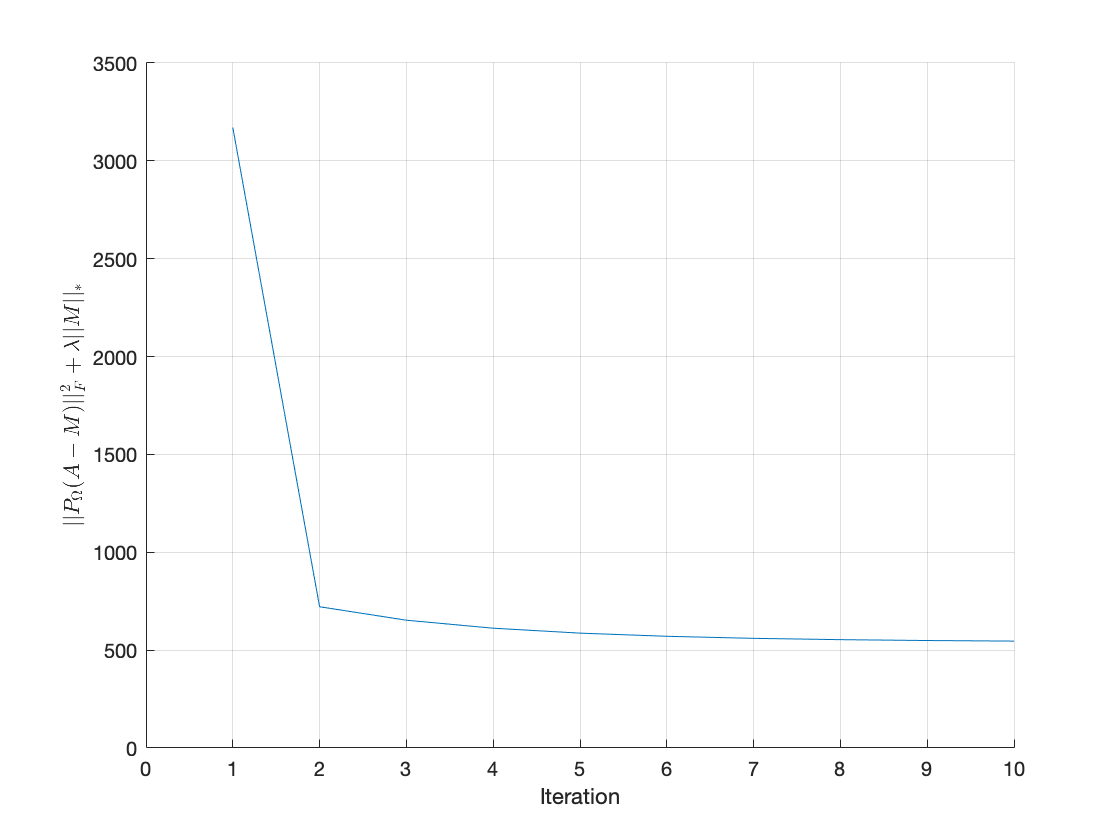

for lambda = 1:9
    [f, M] = NNT(A,lambda,maxiter,M0);
    close all;
    figure;
    hold on; grid;
    hist(reshape(M,[n*m 1]));
    xlim([0,5.5]);
    ylim([0,200]);
    xlabel('Ratings');
    ylabel('Number of Entries');
    saveas(gcf,['figures/nnt_m_' num2str(lambda) '.png']);
    close all;
    figure;
    hold on; grid;
    plot(1:maxiter+1, f);
    ylim([0 3500]);
    xlim([0 maxiter]);
    xlabel('Iteration');
    ylabel('$$\frac{1}{2}||P_{\Omega}(A-M)||_F^2+\lambda||M||_*$$','interpreter','latex');   
    saveas(gcf,['figures/nnt_' num2str(lambda) '.png']);
end